# Quadcopter Basics - Configuration and Movement

In this script, let's learn the concepts behind how the quadcopter works, and run some simple simulations to illustrate as we go along. 

For simplicity, we will assume a rigid body dynamic model, assuming all propellers produce unidirectional thrust perpendicular to the quadcopter system.

## Quadcopter Coordinate System

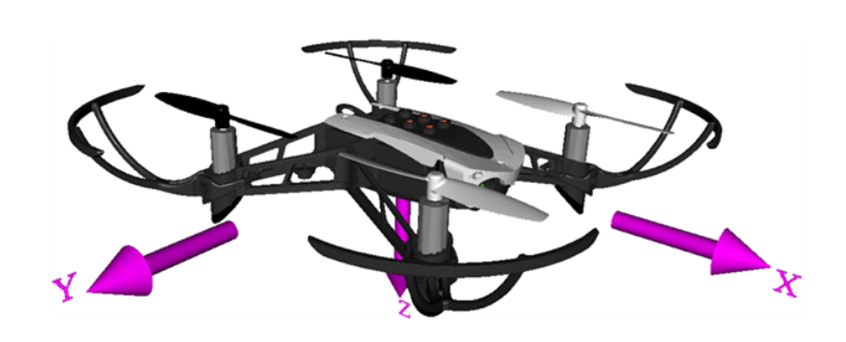

Conventionally, we define the coordinate system for a quadcopter following the right-hand rule with the x-axis pointing 'forward,' the y-axis pointing to the right-hand side and the z-axis pointing downwards. 

### Rotor Configuration

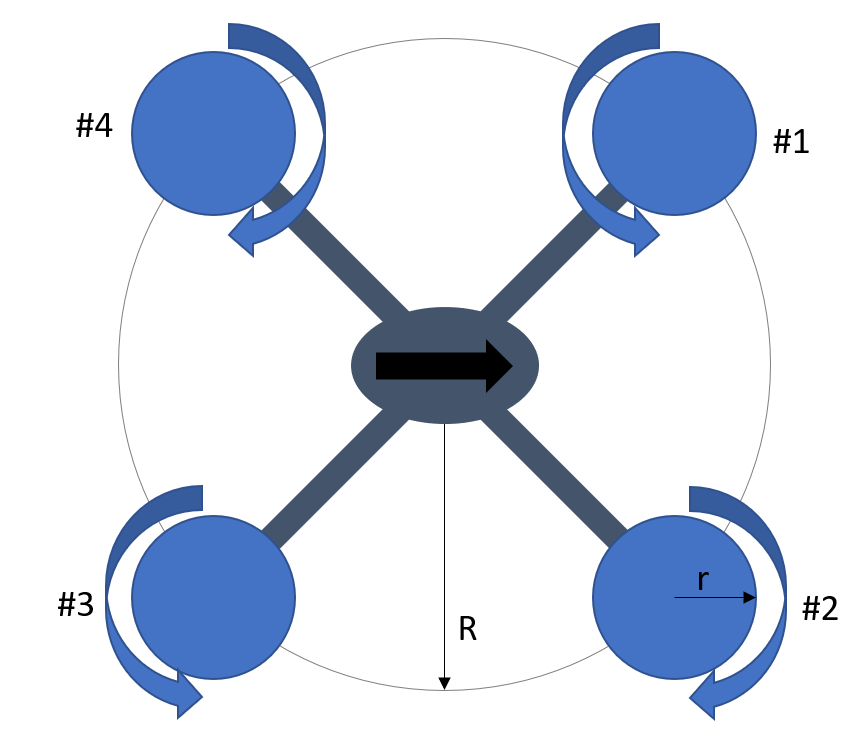

For this course, we will consider the quadcopter being operated by default in the 'x' configuration where the rotors are offset diagonally by 45-degrees to direction of the quadcopter main body. In this configuration, each propeller is placed at an offset of 90-degrees from each other, with its centre being distance *R *away from the body's center-of-mass. Each blade has a radius of *r*, and can spin at a specified angular velocity *w*. 

('+' configurations also exist, but are less commonly used.)

### Quadcopter - Basic Parameters

Let's assume some basic properties to start defining our quadcopter:

M = 0.5; % body mass
m = 0.1; % propeller mass

R = 0.1; % m - arm length
r = 0.02; % m - propeller radius
d = 2*r; % propeller diameter

We can also define a moment of inertia matrix, which will be useful when considering quadcopter rotations.

% Modelling the inertia of the central body as a hollow sphere
Icc = (2/3)*M*d^2

Icc = 5.3333e-04

Ixx = Icc + 4*(0.5*m*r^2 + 0.5*m*R^2) % about x-axis

Ixx = 0.0026

Iyy = Ixx % about y-axis - same as x-axis

Iyy = 0.0026

Izz = Icc + 4*(0.5*m*r^2 + m*R^2)

Izz = 0.0046

### Propeller Modelling

The thrust produced is modelled as a function of the angular velocity and the diameter of the propeller. Under standard modelling techniques for a quadcopter propeller, the thrust T and moment M are given as:


$$T=C_{T\textrm{hrust}} \;\rho \;{\left(\frac{N}{60}\right)}^2 D_p^4$$
 


$$M=C_{\textrm{Moment}} \;\rho \;{\left(\frac{N}{60}\right)}^2 D_p^5$$
 

Where $C_{T\textrm{hrust}}$ & $C_{\textrm{Moment}}$ are dimensionless coefficients, $\rho$ is the air density at the given altitude, N is the angular speed of the propeller in rpm & $D_p$is the diameter.

Assuming the rotors exactly counter-act the weight of the quadcopter at a nominal angular speed of 4000rpm, 


$${4*\;T}_{\textrm{prop}} =\;\left(M+4*m\right)*g$$


This will let us calculate an approximate value for thrust coefficient $C_T$.

g = 9.81; % m/s^2
rho = 1.225; % air density at sea level kg/m^3

% Quadcopter weight
W = (M+m*4)*g

W = 8.8290

% for single propeller
T_prop = (M + 4*m)*g/4

T_prop = 2.2073

N = 4000 % rpm - nominal value

N = 4000

C_thrust = T_prop/( rho * (N/60)^2 * d^4)

C_thrust = 158.3646

From experimental data [1], we assume a value for $C_M$ as:

C_moment = 89.6

C_moment = 89.6000

For convenience, let us convert $C_{T\textrm{hrust}}$ & $C_{\textrm{Moment}}$ into a form $C_T$ & $C_M$where they can be multiplied directly with $N^2$ to simplify our calculations

Ct = C_thrust*rho*(1/60)^2*d^4

Ct = 1.3795e-07

Cm = C_moment*rho*(1/60)^2*d^5

Cm = 3.1221e-09

#### Performance Curves - Torque & Moment vs Speed

This gives the performance curves of the propellers as seen below:

N = 0:1000:10000; % sweeping speed values from 0 - 10,000 rpm
T_sweep = Ct * N.^2;
M_sweep = Cm * N.^2;

Plotting:

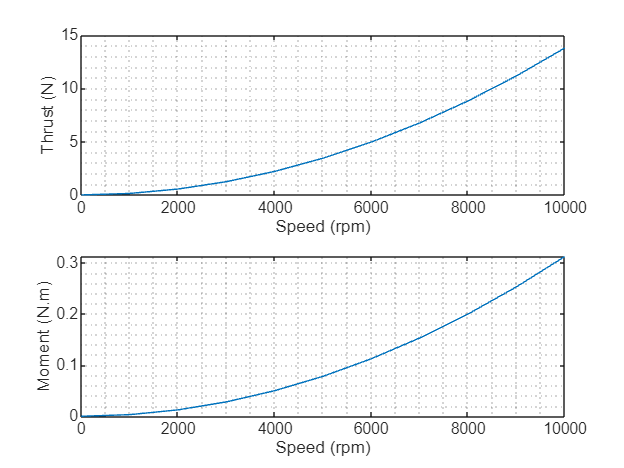

subplot(2,1,1)
plot(N, T_sweep)
xlabel('Speed (rpm)')
ylabel('Thrust (N)')
grid minor

subplot(2,1,2)
plot(N, M_sweep)
xlabel('Speed (rpm)')
ylabel('Moment (N.m)')
grid minor

These numbers will give us an easy reference for future calculations or design decisions.

## Forces and Torques

Now that we understand the propeller configurations, let's use the knowledge gained so far to model how the forces and moments from the propellers act on the quadcopter. 

The rotors are numbered 1 through 4, and opposite rotors (1/3 & 2/4) rotate in the same direction in order to cancel out their reaction moments. In a 'hover' condition, the total thrust produced by all rotors should cancel out the weight exactly, and the rotational moments should all cancel out to zero. 

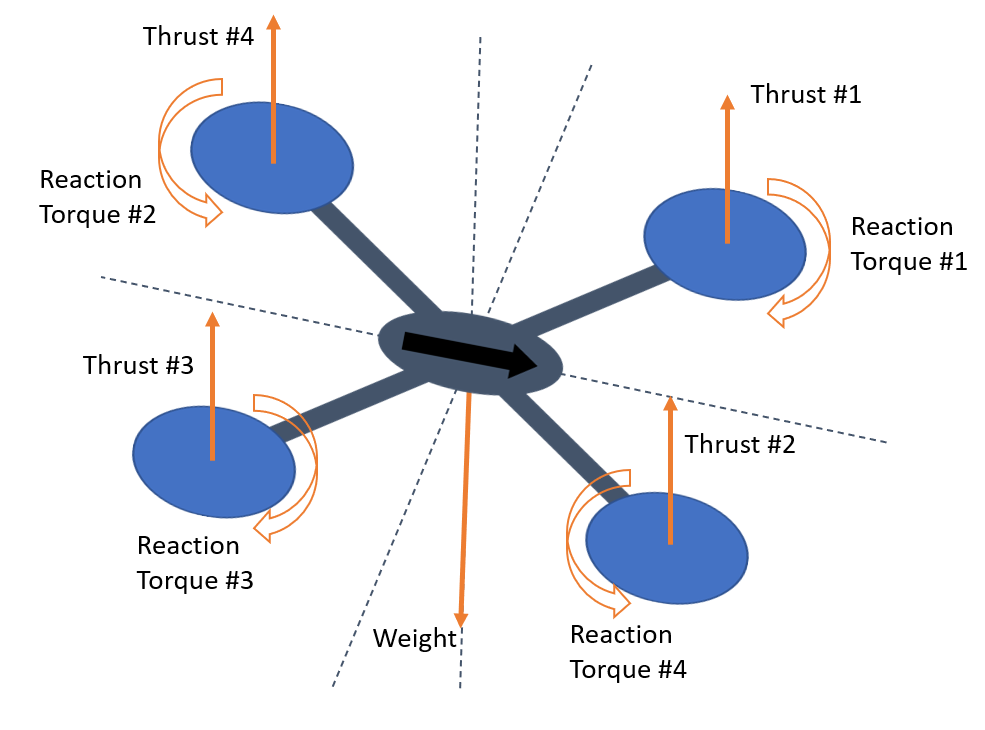

For an 'X' - shaped quadcopter, the total thrust force can be computed as follows:


$$f=C_T \;\left(w_1^2 +w_2^2 \;{+\;w}_3^2 +w_4^2 \;\right)$$


Similarly, we can compute the moments as:


$$\tau_x ={R\;C}_T \;\left(\frac{\sqrt{2}}{2}w_1^2 -\frac{\sqrt{2}}{2}w_2^2 -\frac{\sqrt{2}}{2}w_3^2 +\frac{\sqrt{2}}{2}w_4^2 \right)$$



$$\tau_y =RC_T \;\left(\frac{\sqrt{2}}{2}w_1^2 +\frac{\sqrt{2}}{2}w_2^2 -\frac{\sqrt{2}}{2}w_3^2 -\frac{\sqrt{2}}{2}w_4^2 \right)$$



$$\tau_z =C_M \;\left(w_1^2 -w_2^2 \;{+\;w}_3^2 -w_4^2 \;\right)$$


This can be expressed in a convenient matrix form as follows:


$$\left\lbrack \begin{array}{c}
f\\
\tau_x \\
\tau_y \\
\tau_z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
C_T  & C_T  & C_T  & C_T \\
\frac{RC_T }{\sqrt{2}} & -\frac{RC_T }{\sqrt{2}} & -\frac{RC_T }{\sqrt{2}} & \frac{RC_T }{\sqrt{2}}\\
\frac{RC_T }{\sqrt{2}} & \frac{RC_T }{\sqrt{2}} & -\frac{RC_T }{\sqrt{2}} & -\frac{RC_T }{\sqrt{2}}\\
C_M  & {-C}_M  & C_M  & {-C}_M 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
w_1^2 \\
w_2^2 \\
w_3^2 \\
w_4^2 
\end{array}\right\rbrack$$


quad_m = [Ct, Ct, Ct, Ct;...
         R*Ct/sqrt(2), -R*Ct/sqrt(2), -R*Ct/sqrt(2), R*Ct/sqrt(2);...
         R*Ct/sqrt(2), R*Ct/sqrt(2), -R*Ct/sqrt(2), -R*Ct/sqrt(2);...
         Cm, -Cm, Cm, -Cm]

quad_m = 1.0e-06 *

    0.1380    0.1380    0.1380    0.1380
    0.0098   -0.0098   -0.0098    0.0098
    0.0098    0.0098   -0.0098   -0.0098
    0.0031   -0.0031    0.0031   -0.0031


In a steady state, where all the propellers are spinning at the nominal speed (say 4000 rpm), all the moments cancel themselves out and a residual force remains. 

w = [4000 4000 4000 4000] 

w =         4000        4000        4000        4000


f = quad_m*w'.^2

f =     8.8290
         0
         0
         0


We can check that the total thrust force is equal to the weight of the quadcopter, as per our design. By convention, the thrust force acts in a direction opposite to the weight, thereby allowing the quadcopter to hover.

f(1) - W

ans = -1.7764e-15

Any change from this condition will lead to movement of one type or another, which is explained in detail in the next script: [Quadcopter Basics - Movement](matlab:open('./quadcopterMovement.mlx'))

We can also save the above parameters for reuse.

save('quad_params.mat',"M","m","R","r","d","Icc","Ixx","Iyy","Izz","quad_m","W","Ct","Cm","g",'-mat')

### References

- Quan, Quan. *Introduction to multicopter design and control*. Singapore: Springer, 2017.

Copyright © MathWorks Inc. 2022